% 灰色预测
clear
syms a b;
c=[a b]';
%125786
%A=[1629 1490 1348 1346 1333 1271 1268 1237 1135 1025 957 884 826 774 761 768]
A=[126743 127627 128453 129227 129988 130756 131448 132129 132802 133450 134091 134735 135404 136072 136782 137462];
%A=[957 884 826    774    761    768    692    681    673    648    641    644    669    668    710    680]%1999-2015年增长值
B=cumsum(A) % 原始数据累加224.2955

B =       126743      254370      382823      512050      642038      772794      904242     1036371     1169173     1302623     1436714     1571449     1706853     1842925     1979707     2117169


n=length(A);
for i=1:(n-1)
    C(i)=(B(i)+B(i+1))/2;  % 生成累加矩阵
end
% 计算待定参数的值
D=A;D(1)=[];
D=D';
E=[-C;ones(1,n-1)];
c=inv(E*E')*E*D;
c=c';
a=c(1)

a =       -0.00519786149237874


b=c(2)

b =           126930.261253398


value1=b/a

value1 =          -24419708.2664683


value2=A(1)-b/a%[A(1)-b/a]*e^(-a*(i-1))+b/a

value2 =           24546451.2664683


% 预测后续数据
F=[];F(1)=A(1);
for i=2:(n+16)
    F(i)=(A(1)-b/a)/exp(a*(i-1))+b/a ;
end
G=[];G(1)=A(1);
for i=2:(n+16)
    G(i)=F(i)-F(i-1); %得到预测出来的数据
end 
%模型检验

H = G(1:16);
%计算残差序列
epsilon = A - H;

%法一：相对残差Q检验
%计算相对误差序列
delta = abs(epsilon./A);
%计算相对误差Q
disp('相对残差Q检验：')

相对残差Q检验：


Q = mean(delta)

Q =       0.000756392604863556



%法二：方差比C检验
disp('方差比C检验：')

方差比C检验：


C = std(epsilon, 1)/std(A, 1)

C =         0.0379274657844936



%法三：小误差概率P检验
S1 = std(A, 1);
tmp = find(abs(epsilon - mean(epsilon))< 0.6745 * S1);
disp('小误差概率P检验：')

小误差概率P检验：


P = length(tmp)/n

P =      1



t1=2000:2015;
t2=2000:2031;
G

G =                     126743          127921.224203207          128587.872079268           129257.99411995          129931.608430475          130608.733210459          131289.386754327           131973.58745186          132661.353788678           133352.70434672          134047.657804787          134746.232938997          135448.448623348          136154.323830158          136863.877630662          137577.129195448          138294.097795017           139014.80280032          139739.263683215          140467.500017077          141199.531477265          141935.377841674          142675.058991265          143418.594910622          144166.005688474          144917.311518218          145672.532698523          146431.689633805          147194.802834842          147961.892919302          148732.980612267          149508.086746868


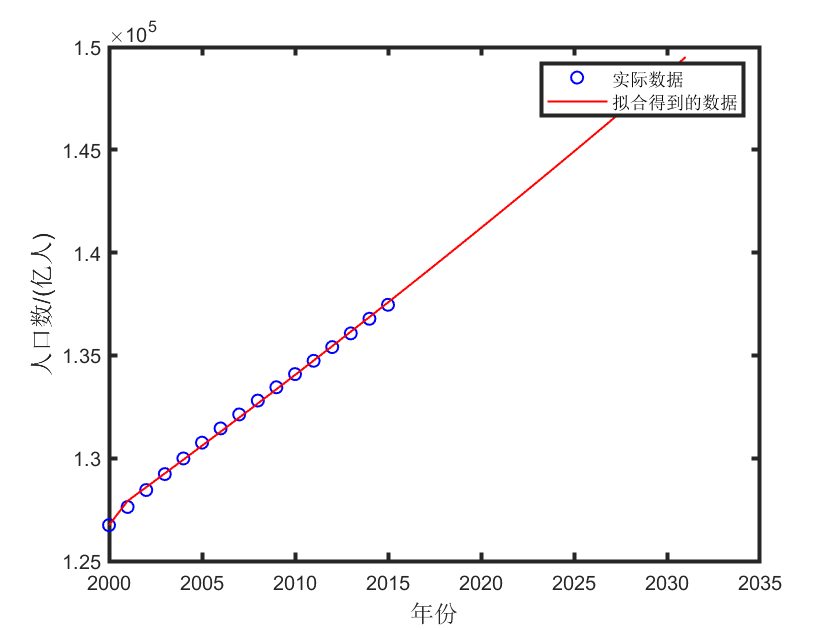

plot(t1,A,'bo', 'LineWidth',1)
hold on
plot(t2,G,'-r', 'LineWidth',1)
xlabel('年份', 'fontsize',12)
ylabel('人口数/(亿人)','fontsize',12)
set(gca,  'LineWidth',2);
legend('实际数据','拟合得到的数据')